% Define the file path (change 'your_file_path' to the actual path of your Excel file)
filename = 'ADC_Rawdata.xlsx';
% Load the data from the Excel file
data = readtable(filename);

% Current testing
% Trial 1
id_psu1 = data{1:31, 2};              % ID measured by power supply
Vid_scope1 = data{1:31, 5};           % voltage from hall effect sensor measured with oscilloscope
Vid_dn1 = data{1:31, 9};              % voltage from hall effect sensor measured with ADC
id_scope1 = (Vid_scope1 - 0.5) / 0.8; % current calculated from Vid
id_dn1 = (Vid_dn1 - 0.5) / 0.8;       % current calculated from Vid_scope
id1_total_err = (id_psu1 - id_dn1);   % difference between expected and measured
id1_total_err_percent = (id1_total_err ./ id_psu1) .* 100; % same as above, just in percent

% Trial 2
id_psu2 = data{35:65, 2};
Vid_scope2 = data{35:65, 5};
Vid_dn2 = data{35:65, 9};
id_scope2 = (Vid_scope2 - 0.5) / 0.8;
id_dn2 = (Vid_dn2 - 0.5) / 0.8;
id2_total_err = (id_psu2 - id_dn2);
id2_total_err_percent = (id2_total_err ./ id_psu2) .* 100;

% Trial 3
id_psu3 = data{69:99, 2};
Vid_scope3 = data{69:99, 5};
Vid_dn3 = data{69:99, 9};
id_scope3 = (Vid_scope3 - 0.5) / 0.8;
id_dn3 = (Vid_dn3 - 0.5) / 0.8;
id3_total_err = (id_psu3 - id_dn3);
id3_total_err_percent = (id3_total_err ./ id_psu3) .* 100;

% Trial 4
id_psu4 = data{103:133, 2};
Vid_scope4 = data{103:133, 5};
Vid_dn4 = data{103:133, 9};
id_scope4 = (Vid_scope4 - 0.5) / 0.8;
id_dn4 = (Vid_dn4 - 0.5) / 0.8;
id4_total_err = (id_psu4 - id_dn4);
id4_total_err_percent = (id4_total_err ./ id_psu4) .* 100;

% Average of all trials
id_psu_avg = (id_psu1 + id_psu2 + id_psu3 + id_psu4) / 4;
Vid_scope_avg = (Vid_scope1 + Vid_scope2 + Vid_scope3 + Vid_scope4) / 4;
Vid_dn_avg = (Vid_dn1 + Vid_dn2 + Vid_dn3 + Vid_dn4) / 4;
id_scope_avg = (id_scope1 + id_scope2 + id_scope3 + id_scope4) / 4;
id_dn_avg = (id_dn1 + id_dn2 + id_dn3 + id_dn4) / 4;

% Ideal values
id_ideal = id_psu_avg;

% Error calculation, uses averages of all trials
id_hall_err = (id_psu_avg - id_scope_avg); % hall effect error, difference between PSU value and scope value 
id_dn_err = (id_scope_avg - id_dn_avg); % ADC error, difference between scope value and ADC value
id_total_err = (id_psu_avg - id_dn_avg); % total system error, difference between PSU value and ADC value
id_total_err_percent = (id_total_err ./ id_psu_avg) .* 100;

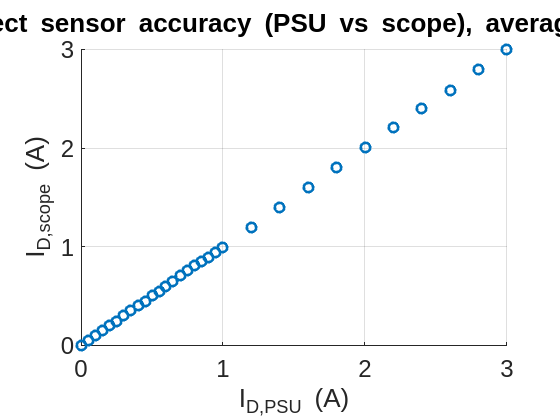

% Plot recorded data

% Hall effect sensor accuracy
figure;
scatter(id_psu_avg, id_scope_avg, 50, "LineWidth", 2);
title("I_{D} Hall effect sensor accuracy (PSU vs scope), average of 4 trials");
xlabel("I_{D,PSU} (A)");
ylabel("I_{D,scope} (A)");
grid on;
set(gca,'FontSize',18);

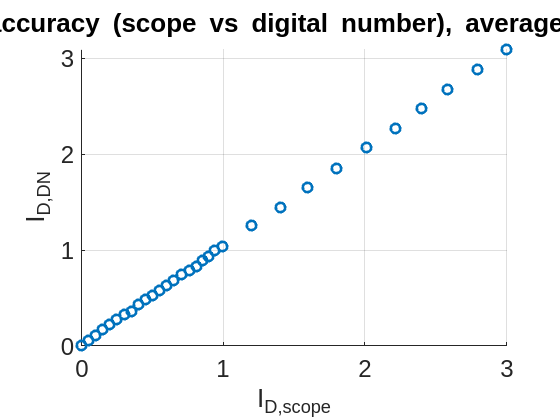


% ADC accuracy when measuring ID
figure;
scatter(id_scope_avg, id_dn_avg, 50, "LineWidth", 2);
title("I_{D} ADC accuracy (scope vs digital number), average of 4 trials");
xlabel("I_{D,scope}");
ylabel("I_{D,DN}")
grid on;
set(gca,'FontSize',18);

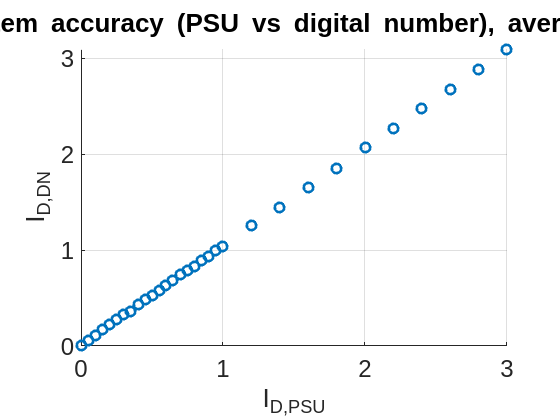


% Total system accuracy measuring ID
figure;
scatter(id_psu_avg, id_dn_avg, 50, "LineWidth", 2);
title("I_{D} Total system accuracy (PSU vs digital number), average of 4 trials");
xlabel("I_{D,PSU}");
ylabel("I_{D,DN}");
grid on; 
set(gca,'FontSize',18);

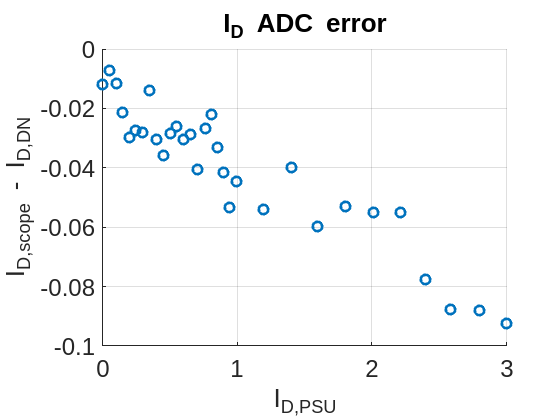


figure;
scatter(id_scope_avg, id_dn_err, 50, "LineWidth", 2);
title("I_{D} ADC error");
xlabel("I_{D,PSU}");
ylabel("I_{D,scope} - I_{D,DN}");
grid on;
set(gca,'FontSize',18)

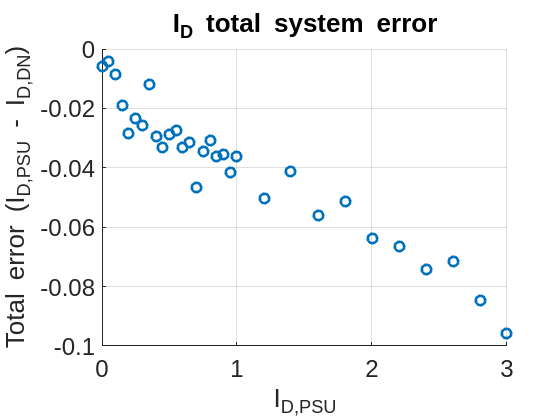


figure;
scatter(id_psu_avg, id_total_err, 50, "LineWidth", 2);
title("I_{D} total system error");
xlabel("I_{D,PSU}");
ylabel("Total error (I_{D,PSU} - I_{D,DN})")
grid on;
set(gca,'FontSize',18)

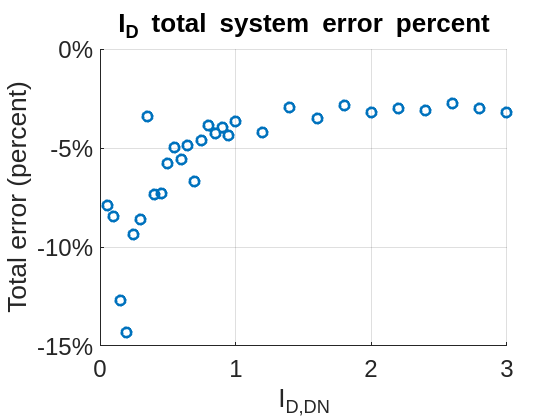


figure;
scatter(id_psu_avg, id_total_err_percent, 50, "LineWidth", 2);
title("I_{D} total system error percent");
xlabel("I_{D,DN}");
ylabel("Total error (percent)");
ytickformat('percentage');
grid on;
set(gca,'FontSize',18)

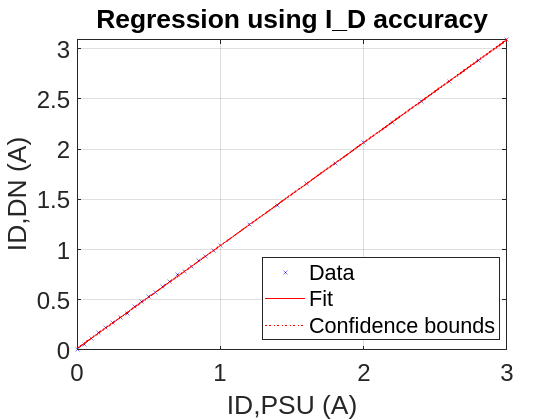

% linear regression analysis using accuracy data
[value_regression, gain_comp, offset_comp] = ADCregression(id_psu_avg, id_dn_avg);

figure;
plot(value_regression);
title("Regression using I_D accuracy");
xlabel("ID,PSU (A)");
ylabel("ID,DN (A)");
grid on;
set(gca,'FontSize',18)

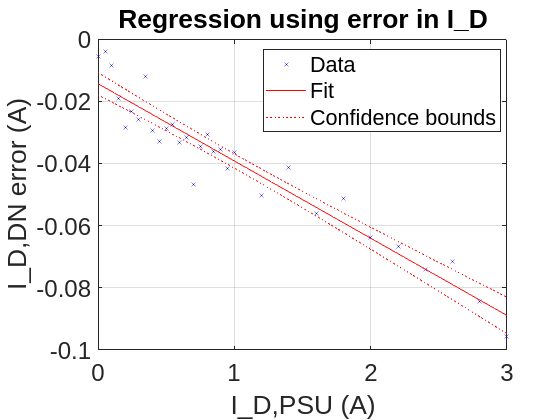

% Linear regression using error in ID instead
[error_regression, error_gain, error_offset] = ADCregression(id_psu_avg, id_total_err);

figure;
plot(error_regression);
title("Regression using error in I_D");
xlabel("I_D,PSU (A)");
ylabel("I_D,DN error (A)");
grid on;
set(gca,'FontSize',18)

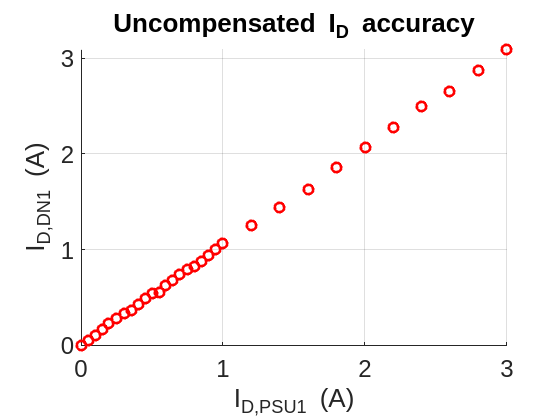

% Try compensating an individual trial

% Plot uncompensated data
figure;
scatter(id_psu1, id_dn1, 50, 'r', "LineWidth", 2);
title("Uncompensated I_{D} accuracy");
xlabel("I_{D,PSU1} (A)");
ylabel("I_{D,DN1} (A)");
grid on;
set(gca,'FontSize',18)

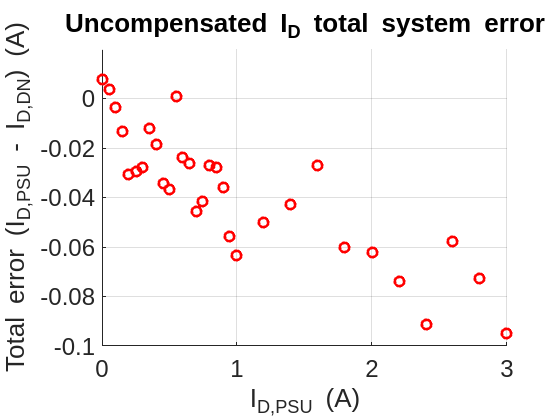


figure;
scatter(id_psu1, id1_total_err, 50, 'r', "LineWidth", 2);
title("Uncompensated I_{D} total system error");
xlabel("I_{D,PSU} (A)");
ylabel("Total error (I_{D,PSU} - I_{D,DN}) (A)");
grid on;
set(gca,'FontSize',18)

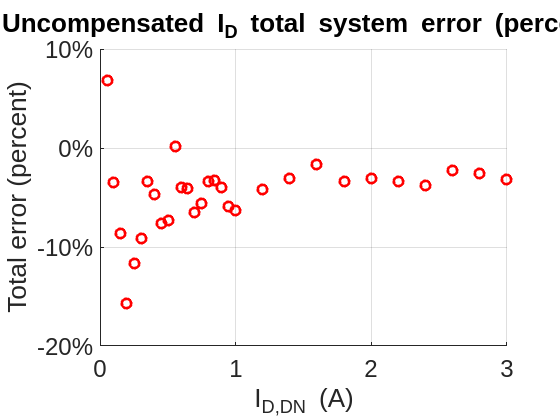


figure;
scatter(id_psu1, id1_total_err_percent, 50, 'r', "LineWidth", 2);
title("Uncompensated I_{D} total system error (percent)");
xlabel("I_{D,DN} (A)");
ylabel("Total error (percent)");
ytickformat('percentage');
grid on;
set(gca,'FontSize',18)

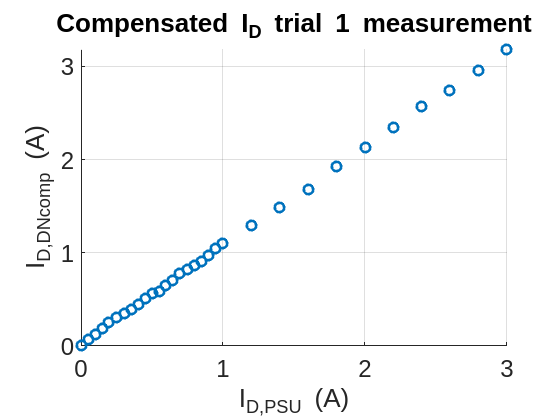


% Compensate using linear regression based on actual value vs measured
id_dn1_comp = id_dn1.*gain_comp + offset_comp;
id_dn1_comp_error = id_psu1 - id_dn1_comp;
id_dn1_comp_error_percent = (id_dn1_comp_error ./ id_psu1) .* 100;

% Plot results
figure;
scatter(id_psu1, id_dn1_comp, 50, "LineWidth", 2);
title("Compensated I_{D} trial 1 measurement");
xlabel("I_{D,PSU} (A)");
ylabel("I_{D,DNcomp} (A)");
grid on;
set(gca,'FontSize',18)

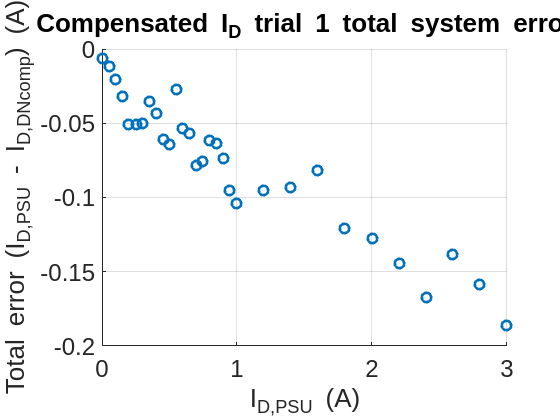


figure;
scatter(id_psu1, id_dn1_comp_error, 50, "LineWidth", 2);
title("Compensated I_{D} trial 1 total system error");
xlabel("I_{D,PSU} (A)");
ylabel("Total error (I_{D,PSU} - I_{D,DNcomp}) (A)")
grid on;
set(gca,'FontSize',18)

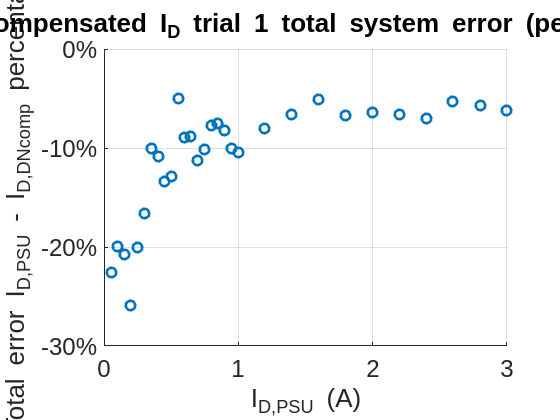


figure;
scatter(id_psu1, id_dn1_comp_error_percent, 50, "LineWidth", 2);
title("Compensated I_{D} trial 1 total system error (percent)");
xlabel("I_{D,PSU} (A)");
ylabel("Total error I_{D,PSU} - I_{D,DNcomp} percentage");
ytickformat('percentage');
grid on;
set(gca,'FontSize',18)

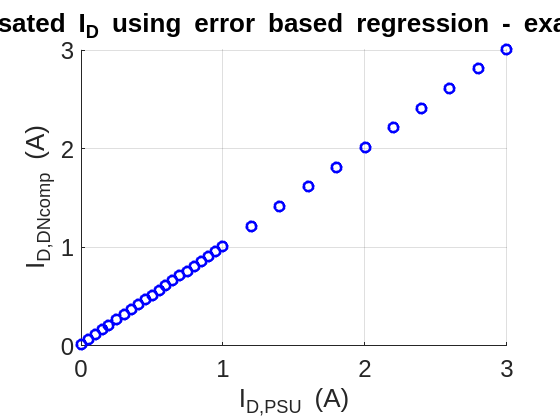


% compensation using linear regression based on actual value vs error in measured value
id1_error_comp = id1_total_err*error_gain + error_offset;
id_dn1_comp_with_error = (id_psu1 - id1_error_comp);
id_dn1_comp_with_error_error = (id_psu1 - id_dn1_comp_with_error); % total system error, difference between PSU value and ADC value
id_dn1_comp_with_error_error_percent = ((id_psu1 - id_dn1_comp_with_error)./(id_psu1)).*100;

% Plot results
figure;
scatter(id_psu1, id_dn1_comp_with_error, 50, 'b', "LineWidth", 2);
title("Compensated I_{D} using error based regression - example data");
xlabel("I_{D,PSU} (A)");
ylabel("I_{D,DNcomp} (A)")
grid on;
set(gca,'FontSize',18)

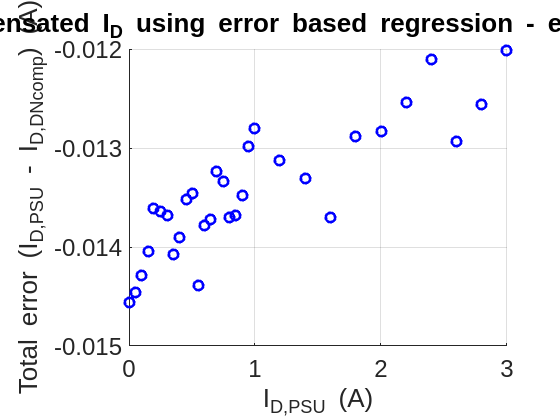


% plot of error
figure;
scatter(id_psu1, id_dn1_comp_with_error_error, 50, 'b', "LineWidth", 2);
title("Compensated I_{D} using error based regression - example data");
xlabel("I_{D,PSU} (A)");
ylabel("Total error (I_{D,PSU} - I_{D,DNcomp}) (A)");
grid on;
set(gca,'FontSize',18);

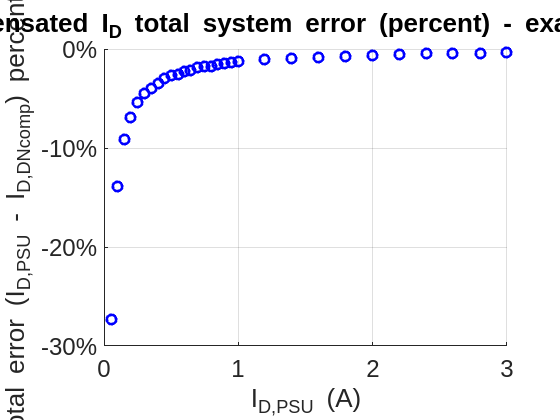


% plot of error percentage
figure;
scatter(id_psu1, id_dn1_comp_with_error_error_percent, 50, 'b', "LineWidth", 2);
title("Compensated I_{D} total system error (percent) - example data");
xlabel("I_{D,PSU} (A)");
ylabel("Total error (I_{D,PSU} - I_{D,DNcomp}) percentage");
ytickformat('percentage');
grid on;
set(gca,'FontSize',18);

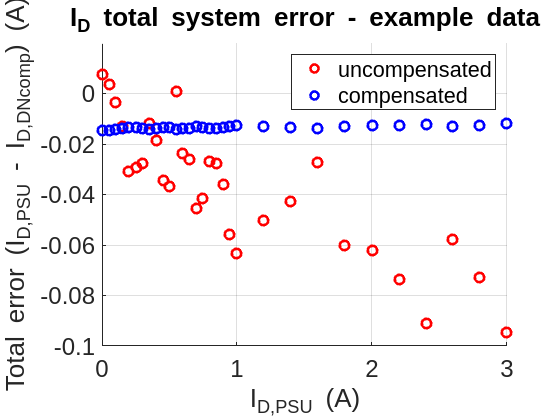

% Overlay both uncompensated and compensated

% error
figure;
scatter(id_psu1, id1_total_err, 50, 'r', "LineWidth", 2);
hold on;
scatter(id_psu1, id_dn1_comp_with_error_error, 50, 'b', "LineWidth", 2);
title("I_{D} total system error - example data");
xlabel("I_{D,PSU} (A)");
ylabel("Total error (I_{D,PSU} - I_{D,DNcomp}) (A)");
legend('uncompensated','compensated');
grid on;
set(gca,'FontSize',18);

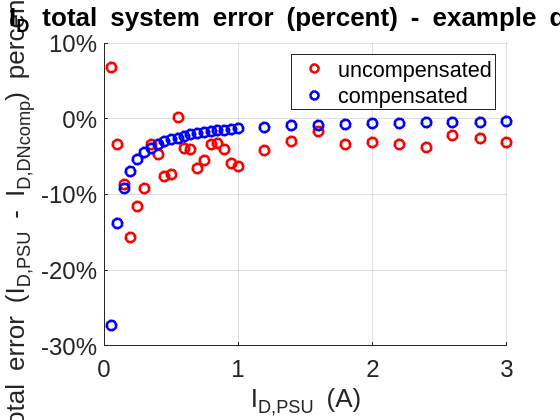


% percent error
figure;
scatter(id_psu1, id1_total_err_percent, 50, 'r', "LineWidth", 2);
hold on;
scatter(id_psu1, id_dn1_comp_with_error_error_percent, 50, 'b', "LineWidth", 2);
title("I_{D} total system error (percent) - example data");
xlabel("I_{D,PSU} (A)");
ylabel("Total error (I_{D,PSU} - I_{D,DNcomp}) percentage");
ytickformat('percentage');
legend('uncompensated','compensated');
grid on;
set(gca,'FontSize',18);

% Vds testing
% Trial 1
Vds_psu1 = data{1:31, 3};                  % Vds measured by power supply
Vds_scope1 = data{1:31, 6};                % Vds measured by scope
Vds_div_scope1 = data{1:31, 7};            % Vds_div measured by scope, should be 3/5 of Vds. This is what the ADC is reading.
Vds_calc_scope1 = Vds_div_scope1 .* (5/3); % Vds calculated from Vds_div_scope
Vds_div_dn1 = data{1:31, 10};              % Vds_div measured by ADC
Vds_dn1 = Vds_div_dn1 .* (5/3);            % Vds calculated from Vds_div_dn (Vds measured by ADC)
Vds_total_err1 = (Vds_scope1 - Vds_dn1);     % Difference between expected and measured
Vds_total_err1_percent = (Vds_total_err1 ./ Vds_psu1) .* 100; % same as above, just in percent

% Trial 2
Vds_psu2 = data{35:65, 3};
Vds_scope2 = data{35:65, 6};
Vds_div_scope2 = data{35:65, 7};
Vds_calc_scope2 = Vds_div_scope2 .* (5/3);
Vds_div_dn2 = data{35:65, 10};
Vds_dn2 = Vds_div_dn2 .* (5/3);
Vds_total_err2 = (Vds_scope2 - Vds_dn2);
Vds_total_err2_percent = (Vds_total_err2 ./ Vds_psu2) .* 100;

% Trial 3
Vds_psu3 = data{69:99, 3};
Vds_scope3 = data{69:99, 6};
Vds_div_scope3 = data{69:99, 7};
Vds_calc_scope3 = Vds_div_scope3 .* (5/3);
Vds_div_dn3 = data{69:99, 10};
Vds_dn3 = Vds_div_dn3 .* (5/3);
Vds_total_err3 = (Vds_scope3 - Vds_dn3);
Vds_total_err3_percent = (Vds_total_err3 ./ Vds_psu3) .* 100;

% Trial 4
Vds_psu4 = data{103:133, 3};
Vds_scope4 = data{103:133, 6};
Vds_div_scope4 = data{103:133, 7};
Vds_calc_scope4 = Vds_div_scope4 .* (5/3);
Vds_div_dn4 = data{103:133, 10};
Vds_dn4 = Vds_div_dn4 .* (5/3);
Vds_total_err4 = (Vds_scope4 - Vds_dn4);
Vds_total_err4_percent = (Vds_total_err4 ./ Vds_psu4) .* 100;

% Average of all trials
Vds_psu_avg = mean(cat(3, Vds_psu1, Vds_psu2, Vds_psu3, Vds_psu4), 3);
Vds_scope_avg = mean(cat(3, Vds_scope1, Vds_scope2, Vds_scope3, Vds_scope4), 3);
Vds_div_scope_avg = mean(cat(3, Vds_div_scope1, Vds_div_scope2, Vds_div_scope3, Vds_div_scope4), 3);
Vds_calc_scope_avg = mean(cat(3, Vds_calc_scope1, Vds_calc_scope2, Vds_calc_scope3, Vds_calc_scope4), 3);
Vds_div_dn_avg = mean(cat(3, Vds_div_dn1, Vds_div_dn2, Vds_div_dn3, Vds_div_dn4), 3);
Vds_dn_avg = mean(cat(3, Vds_dn1, Vds_dn2, Vds_dn3, Vds_dn4), 3);

% Error calculations using averages
Vds_div_err = (Vds_scope_avg - Vds_calc_scope_avg); % Voltage divider error, difference between scope value before and after divider
Vds_dn_err = (Vds_calc_scope_avg - Vds_dn_avg); % ADC error, difference between scope value and ADC value after divider
Vds_total_err = (Vds_scope_avg - Vds_dn_avg); % total system error, difference between scope value and un-divided ADC value
Vds_total_err_percent = (Vds_total_err ./ Vds_scope_avg) .* 100; % Same in percent

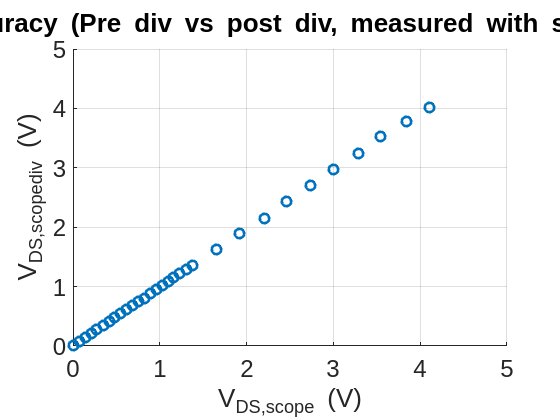

% Some plots of raw data
% figure;
% scatter(Vds_scope1, Vds_calc_scope1, 50, "LineWidth", 2);
% title("V_{DS} Voltage divider accuracy (Pre div vs post div, measured with scope), trial 1");
% xlabel("V_{DS,scope} (V)");
% ylabel("V_{DS,scopediv} (V)");
% grid on;
% set(gca,'FontSize',18);
% 
% figure;
% scatter(Vds_scope2, Vds_calc_scope2, 50, "LineWidth", 2);
% title("V_{DS} Voltage divider accuracy (Pre div vs post div, measured with scope), trial 2");
% xlabel("V_{DS,scope} (V)");
% ylabel("V_{DS,scopediv} (V)");
% grid on;
% set(gca,'FontSize',18);
% 
% figure;
% scatter(Vds_scope3, Vds_calc_scope3, 50, "LineWidth", 2);
% title("V_{DS} Voltage divider accuracy (Pre div vs post div, measured with scope), trial 3");
% xlabel("V_{DS,scope} (V)");
% ylabel("V_{DS,scopediv} (V)");
% grid on;
% set(gca,'FontSize',18);
% 
% figure;
% scatter(Vds_scope4, Vds_calc_scope4, 50, "LineWidth", 2);
% title("V_{DS} Voltage divider accuracy (Pre div vs post div, measured with scope), trial 4");
% xlabel("V_{DS,scope} (V)");
% ylabel("V_{DS,scopediv} (V)");
% grid on;
% set(gca,'FontSize',18);

figure;
scatter(Vds_scope_avg, Vds_calc_scope_avg, 50, "LineWidth", 2);
title("V_{DS} Voltage divider accuracy (Pre div vs post div, measured with scope), average of 4 trials");
xlabel("V_{DS,scope} (V)");
ylabel("V_{DS,scopediv} (V)");
grid on;
set(gca,'FontSize',18);

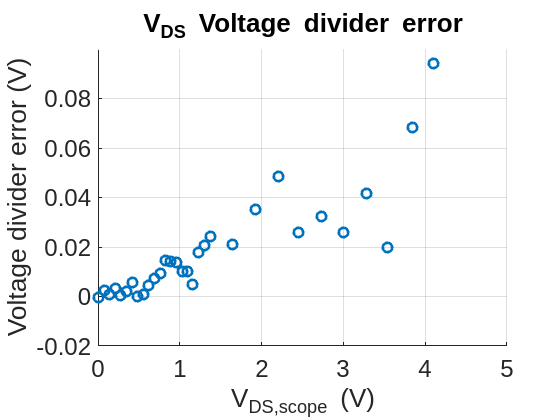


figure;
scatter(Vds_scope_avg, Vds_div_err, 50, "LineWidth", 2);
title("V_{DS} Voltage divider error");
xlabel("V_{DS,scope} (V)");
ylabel("Voltage divider error (V)");
grid on;
set(gca,'FontSize',18);

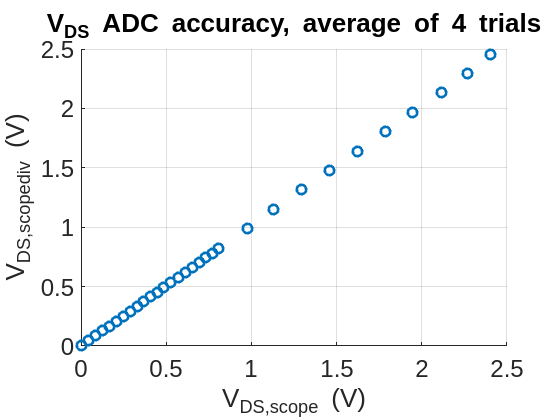



figure;
scatter(Vds_div_scope_avg, Vds_div_dn_avg, 50, "LineWidth", 2);
title("V_{DS} ADC accuracy, average of 4 trials");
xlabel("V_{DS,scope} (V)");
ylabel("V_{DS,scopediv} (V)");
grid on;
set(gca,'FontSize',18);

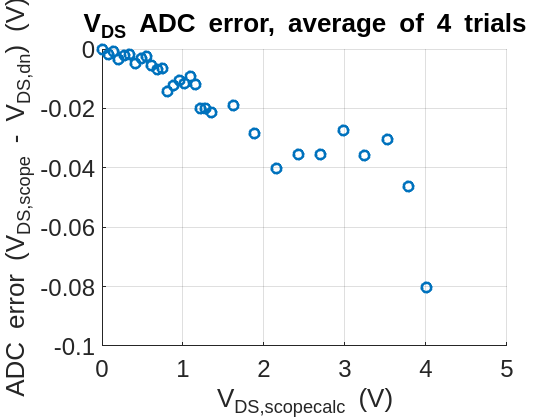


figure;
scatter(Vds_calc_scope_avg, Vds_dn_err, 50, "LineWidth", 2);
title("V_{DS} ADC error, average of 4 trials");
xlabel("V_{DS,scopecalc} (V)");
ylabel("ADC error (V_{DS,scope} - V_{DS,dn}) (V)");
grid on;
set(gca,'FontSize',18);

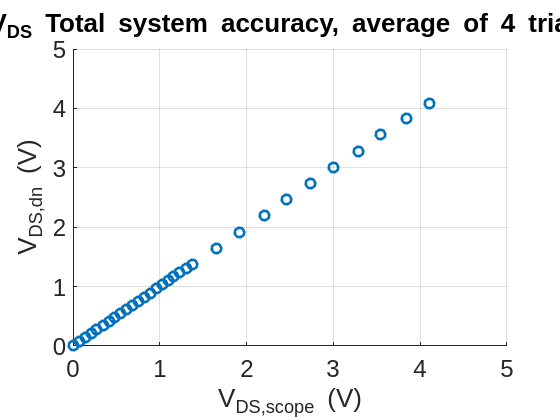


figure;
scatter(Vds_scope_avg, Vds_dn_avg, 50, "LineWidth", 2);
title("V_{DS} Total system accuracy, average of 4 trials");
xlabel("V_{DS,scope} (V)");
ylabel("V_{DS,dn} (V)");
grid on;
set(gca,'FontSize',18);

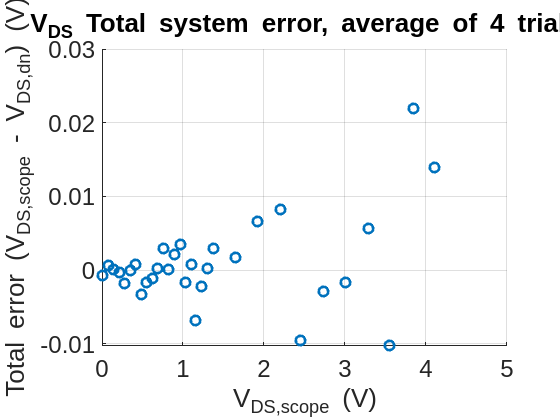


figure;
scatter(Vds_scope_avg, Vds_total_err, 50, "LineWidth", 2);
title("V_{DS} Total system error, average of 4 trials");
xlabel("V_{DS,scope} (V)");
ylabel("Total error (V_{DS,scope} - V_{DS,dn}) (V)");
grid on;
set(gca,'FontSize',18);

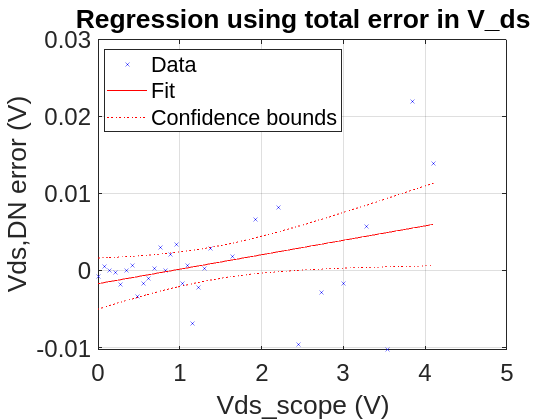

% Regression on total system
% Linear regression using error in Vds
[Vds_error_regression, Vds_error_gain, Vds_error_offset] = ADCregression(Vds_scope_avg, Vds_total_err);

figure;
plot(Vds_error_regression);
title("Regression using total error in V_ds");
xlabel("Vds_scope (V)");
ylabel("Vds,DN error (V)");
grid on;
set(gca,'FontSize',18);


Vds_error_regression.Rsquared

ans = struct with fields:
    Ordinary: 0.132524336728296
    Adjusted: 0.102611382822375


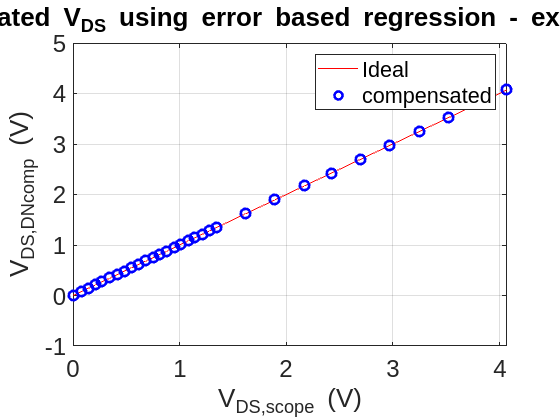

% Attempt to compensate a single trial
Vds1_error_comp = (Vds_total_err1*Vds_error_gain) + Vds_error_offset;
Vds_dn1_comp_with_error = (Vds_scope1 - Vds1_error_comp);
Vds_dn1_comp_with_error_error = (Vds_scope1 - Vds_dn1_comp_with_error); % total system error, difference between PSU value and ADC value
Vds_dn1_comp_with_error_error_percent = (Vds_dn1_comp_with_error_error ./ Vds_scope1) .* 100;

% Plot results
figure;
plot(Vds_scope1, Vds_scope1, 'r');
hold on;
scatter(Vds_scope1, Vds_dn1_comp_with_error, 50, 'b', "LineWidth", 2);
title("Compensated V_{DS} using error based regression - example data");
xlabel("V_{DS,scope} (V)");
ylabel("V_{DS,DNcomp} (V)");
legend('Ideal','compensated');
grid on;
set(gca,'FontSize',18)

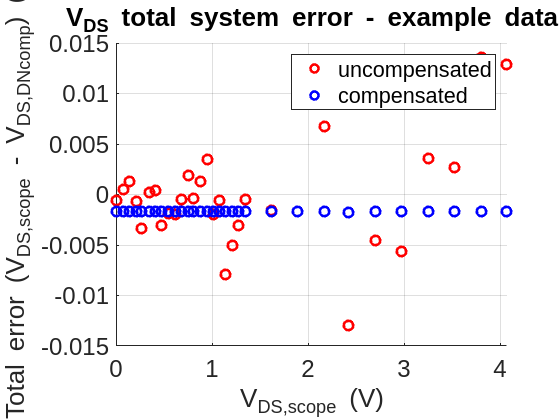


% Overlay both uncompensated and compensated
% error
figure;
scatter(Vds_scope1, Vds_total_err1, 50, 'r', "LineWidth", 2);
hold on;
scatter(Vds_scope1, Vds_dn1_comp_with_error_error, 50, 'b', "LineWidth", 2);
title("V_{DS} total system error - example data");
xlabel("V_{DS,scope} (V)");
ylabel("Total error (V_{DS,scope} - V_{DS,DNcomp}) (V)");
legend('uncompensated','compensated');
grid on;
set(gca,'FontSize',18);

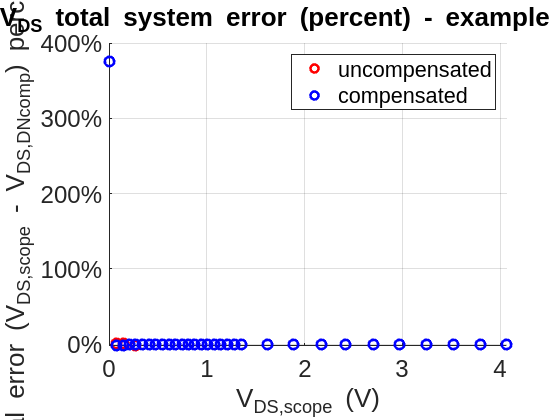


% percent error
figure;
scatter(Vds_scope1, Vds_total_err1_percent, 50, 'r', "LineWidth", 2);
hold on;
scatter(Vds_scope1, Vds_dn1_comp_with_error_error_percent, 50, 'b', "LineWidth", 2);
title("V_{DS} total system error (percent) - example data");
xlabel("V_{DS,scope} (V)");
ylabel("Total error (V_{DS,scope} - V_{DS,DNcomp}) percentage");
ytickformat('percentage');
legend('uncompensated','compensated');
grid on;
set(gca,'FontSize',18);